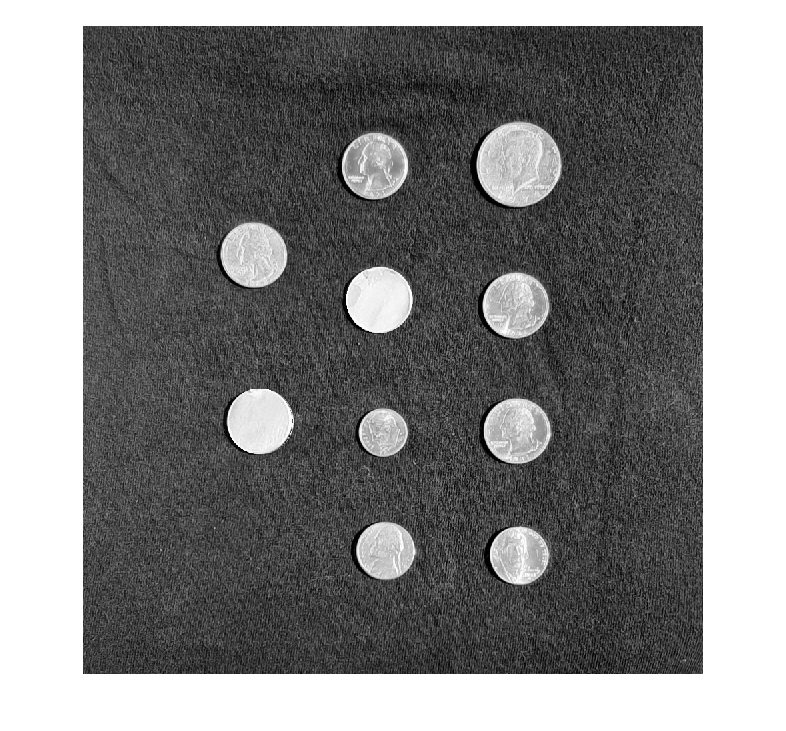

testImageIdx = randi([1,3]);
testCoinImage = imread("testCoinImage"+testImageIdx+".png");
figure, imshow(testCoinImage)

function [BW,maskedImage] = segmentImage(X)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the Image Segmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 25-May-2025
%----------------------------------------------------


% Adjust data to span data range.
X = imadjust(X);

% Find circles
[centers,radii,~] = imfindcircles(X,[25 75],'ObjectPolarity','bright','Sensitivity',0.90);
max_num_circles = Inf;
if max_num_circles < length(radii)
    centers = centers(1:max_num_circles,:);
    radii = radii(1:max_num_circles);
end
BW = circles2mask(centers,radii,size(X,1:2));

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end



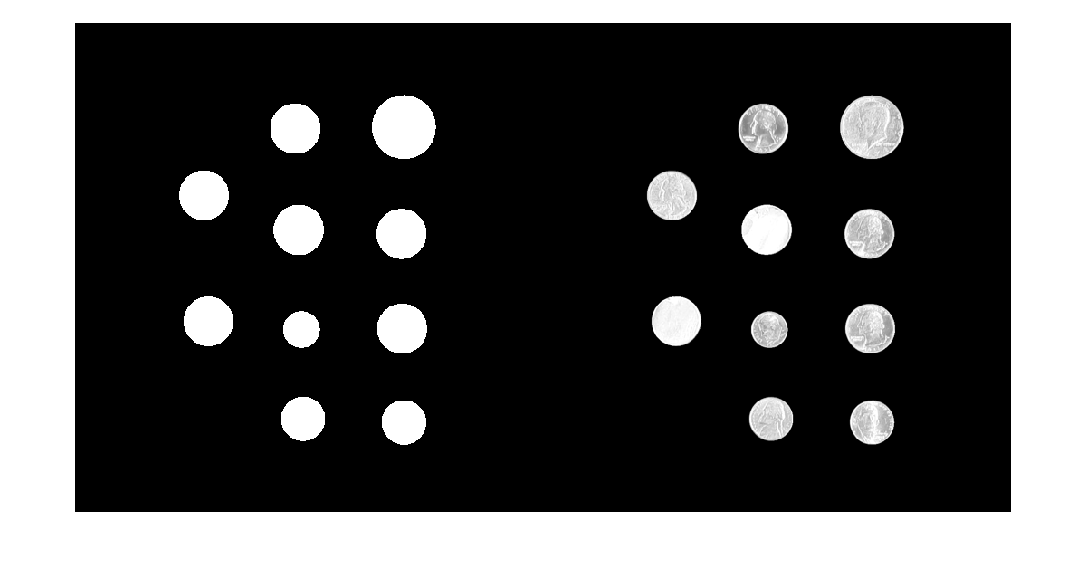

[testCoinMask, maskedTestCoinImage] = segmentImage(testCoinImage);
montage({testCoinMask, maskedTestCoinImage})

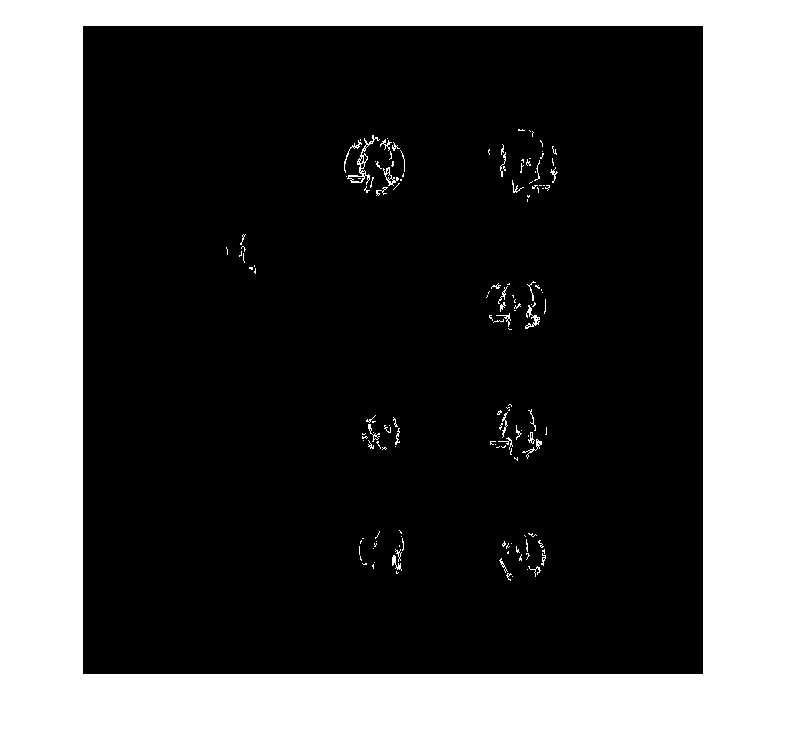

edgeMask = edge(maskedTestCoinImage, 'sobel', 'nothinning');

% Step 2: Erode the coin mask to eliminate rim edges
se = strel('disk', 5); % Disk size can be adjusted
erodedMask = imerode(testCoinMask, se);

% Step 3: Final faceEdgeMask — keep only edges in eroded coin areas
faceEdgeMask = edgeMask & erodedMask;

faceEdgeMask = bwareaopen(faceEdgeMask, 17);  % remove components < 30 pixels

imshow(faceEdgeMask)

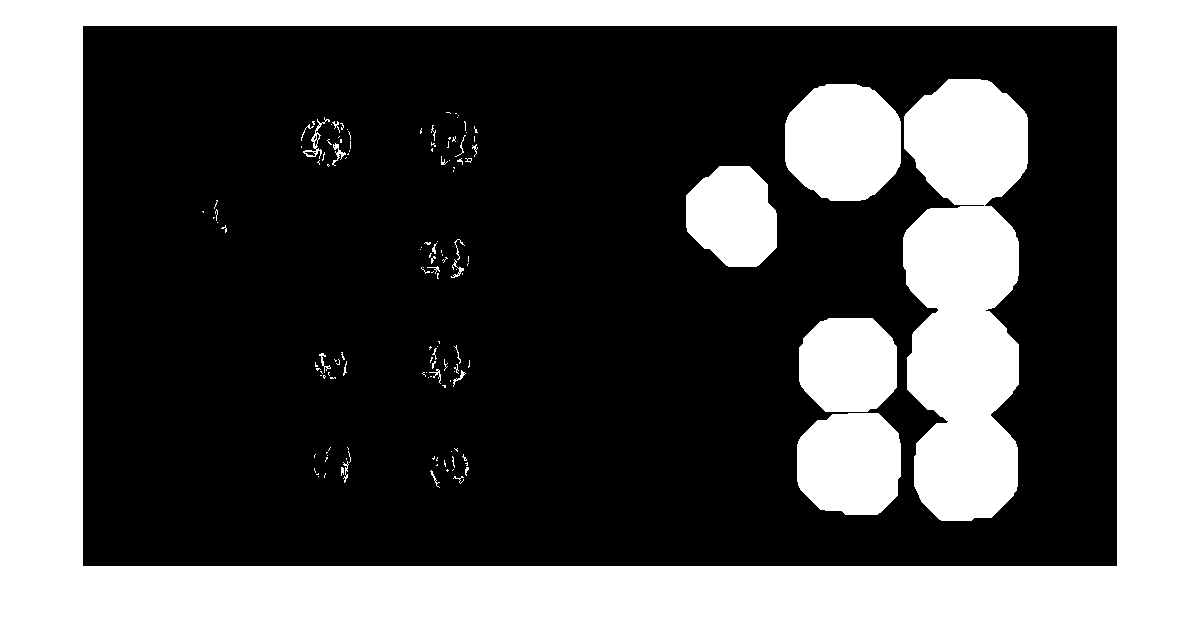

se = strel("disk", 60);
faceEdgeMaskDilated = imdilate(faceEdgeMask, se);

montage({faceEdgeMask, faceEdgeMaskDilated})

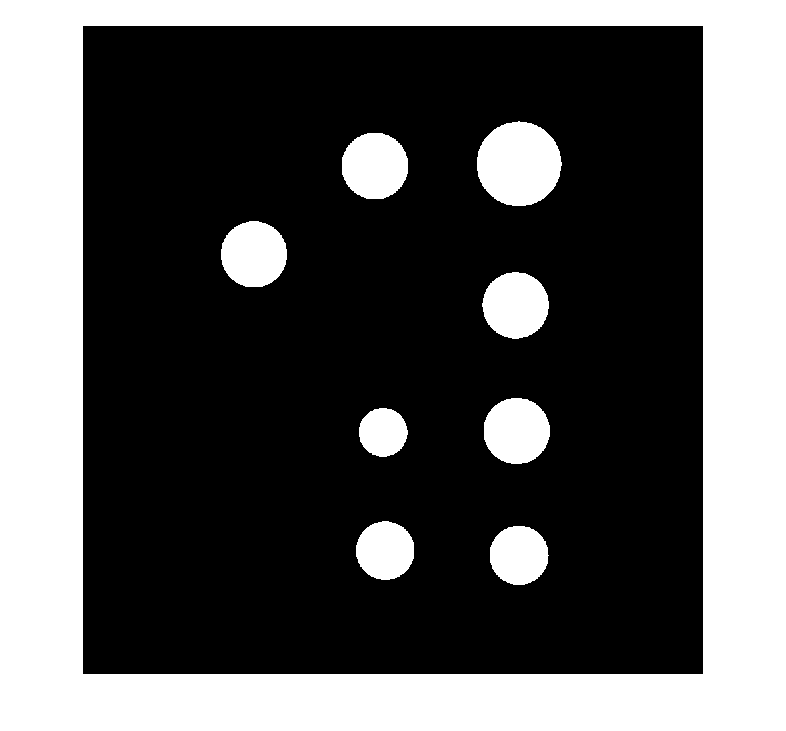


validCoinMask = testCoinMask & faceEdgeMaskDilated ;
imshow(validCoinMask)

cent = 0.50;
quarter = 0.25;
nickel = 0.05;
dime = 0.10;

validCoinProps = regionprops(validCoinMask, "Area");
areas = [validCoinProps.Area];
nDimes = sum(areas < 4500);
nNickels = sum(areas > 6000 & areas < 6200);
nQuarters = sum(areas > 7000 & areas < 8000);
nFiftyCents = sum(areas > 12000);

USD = (nDimes * dime) + (nQuarters * quarter) + (nNickels * nickel) + (nFiftyCents * cent);

fprintf('Total value = $%.2f\n', USD);

Total value = $1.70
